openExample('antenna/atx_pattern_custom')

% M = readmatrix("CustomPattern_testfile.csv");
phiE = [-2.5, -3.3, -4, -4.7, -5, -4.8, -4.7, -3.8, -3.6,-3.3,-3.0,-2.7,-2.5, -2.3, -2.3, -2.2, -2.2, -2.4, -2.6, -2.8, -3, -3.2, -3.4, -3.6, -3.8, -3.3, -2.9, -2.4, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2, -2.2, -2.2, -2.5, -2.5];
thetaE = [-13, -14, -15, -16.2, -17, -15.9, -14.8, -13.6, -11.0, -10, -7.6, -6.3, -5.6, -5, -4.6, -4.7, -5, -5 ,-6, -6.8, -7, -6, -5, -3.6, -3, -3];
thetaE = [thetaE flip(thetaE)]

thetaE =   -13.0000  -14.0000  -15.0000  -16.2000  -17.0000  -15.9000  -14.8000  -13.6000  -11.0000  -10.0000   -7.6000   -6.3000   -5.6000   -5.0000   -4.6000   -4.7000   -5.0000   -5.0000   -6.0000   -6.8000   -7.0000   -6.0000   -5.0000   -3.6000   -3.0000   -3.0000   -3.0000   -3.0000   -3.6000   -5.0000   -6.0000   -7.0000   -6.8000   -6.0000   -5.0000   -5.0000   -4.7000   -4.6000   -5.0000   -5.6000   -6.3000   -7.6000  -10.0000  -11.0000  -13.6000  -14.8000  -15.9000  -17.0000  -16.2000  -15.0000


% thetaE = abs(thetaE)
% thetaE = thetaE / max(thetaE)
M = zeros(180*361, 3);
for j = 1:181
    for i = 1:361
        % q = floor(i-1 / 8);
        M(i + (j - 1) * 360, :) = [i, j, (phiE(floor((i-1) / 8) + 1)) + thetaE(floor((j-1) / 3.6) + 1)];
    end
end

M(1, :) = [0,0,-30]

M =          0         0  -30.0000
    2.0000    1.0000  -15.5000
    3.0000    1.0000  -15.5000
    4.0000    1.0000  -15.5000
    5.0000    1.0000  -15.5000
    6.0000    1.0000  -15.5000
    7.0000    1.0000  -15.5000
    8.0000    1.0000  -15.5000
    9.0000    1.0000  -16.3000
   10.0000    1.0000  -16.3000


## Plot 3D Radiation Pattern on Polar Coordinate System

Specify the electric field magnitude (MagE) vector/matrix along with the theta and phi vectors to plot the 3D radiation pattern on a polar coordinate system. If MagE is a matrix, it must be of size phi-by-theta. If MagE is a vector, then all the 3 arguments MagE, phi and theta must be of the same size.

p = PatternPlotOptions

p =   PatternPlotOptions with properties:

      Transparency: 1
         SizeRatio: 0.9000
    MagnitudeScale: []
     AntennaOffset: [0 0 0]


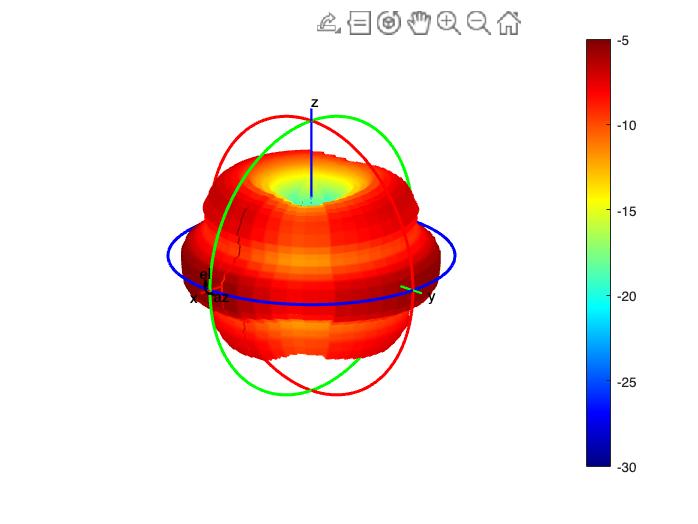

patternCustom(M(:,3),M(:,2),M(:,1),patternOptions=p);